% create Raspberry PI  and RC servo ref-objects
  disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

note: It takes a 10 seconds or so to download code to Raspberry PI 


  [robotPi, blinkLED]= SETUP_pi('192.168.16.68');
% Turn on board LED on and off to signal program has started 
  Blink(robotPi,blinkLED,10);
  disp('Warning! Robot Rover Active! ');  

Warning! Robot Rover Active! 


Next set up you Pi-Cam

% To create a connection to the V2 Pi Camera
robotCam = cameraboard(robotPi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorythms crazy by constantly changing
SETUP_piCam(robotCam);  

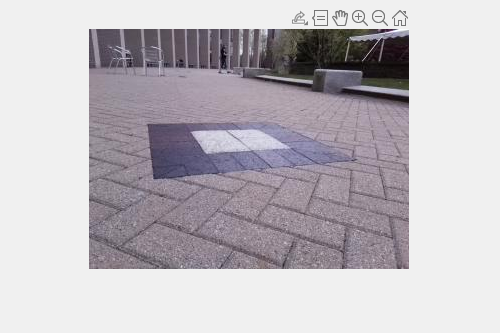


% Acquire a Frame
img = snapshotCustom(robotCam);

% Display the frame in the imaqtool window
% imaqtool launches an interactive GUI to allow you to explore, configure, 
% and acquire data from your installed and supported image acquisition devices.
% imtool(img);                 % can comment this out when you confirm all is working

% explore image with tool
% gCamTest= input('experiment with image tool, type G, then hit ENTER ','s');   % can comment this out when you confirm all is working
% clc;

% livescript does some funky stuff when you try to update in line images quickly, so
% create a free floating figure for images to deal with livescript update problem
piCamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
%figure(piCamWindow)                              % go to camWindow for imshow           
imshow(img)

%image(img)

curve = SENSE_piCam_Waypoint(robotCam,piCamWindow)

Index in position 1 exceeds array bounds (must not exceed 3).

Error in SENSE_piCam_Waypoint (line 54)
    resultsOut(1,:) = centroidsOuter(idxOuter,:);

figure
plot(curve)